Create a simple 2-link RP planar manipulator

A link is defined by a rigid-body object.  Each body is attached to a parent body which is closer to the base of the robot, and has zero or more child body attached to it.

Does not hold any joint configuration state.

link1 = robotics.RigidBody('link1');
joint1 = robotics.Joint('joint1', 'revolute');
joint1.setFixedTransform( transl(0,0,0) );
link1.Joint = joint1;
robot = robotics.RigidBodyTree;

robot.addBody(link1, 'base');

link2 = robotics.RigidBody('link2');
joint2 = robotics.Joint('joint2', 'revolute');
joint2.setFixedTransform( transl(1,0,0) );
link2.Joint = joint2;

robot.addBody(link2, 'link1');

endeffector = robotics.RigidBody('endeffector');
endeffector.Joint.setFixedTransform( transl(1,0,0) );
robot.addBody(endeffector, 'link2');
robot

robot =   RigidBodyTree with properties:

    NumBodies: 3
       Bodies: {[1×1 robotics.RigidBody]  [1×1 robotics.RigidBody]  [1×1 robotics.RigidBody]}
    BodyNames: {'link1'  'link2'  'endeffector'}
     BaseName: 'base'



config = robot.randomConfiguration;
getTransform(robot, config, 'base', 'endeffector')

ans =    -0.1210   -0.9927         0   -0.9302
    0.9927   -0.1210         0    1.5802
         0         0    1.0000         0
         0         0         0    1.0000


robot.showdetails()

--------------------
Robot: (3 bodies)

 Idx          Body Name             Joint Name             Joint Type          Parent Name(Idx)   Children Name(s)
 ---          ---------             ----------             ----------          ----------------   ----------------
   1              link1                 joint1               revolute                   base(0)   link2(2)  
   2              link2                 joint2               revolute                  link1(1)   endeffector(3)  
   3        endeffector        endeffector_jnt                  fixed                  link2(2)   
--------------------




clf
plotbrowser

q = robot.homeConfiguration

q =   1×2 struct array with fields:

    JointName
    JointPosition


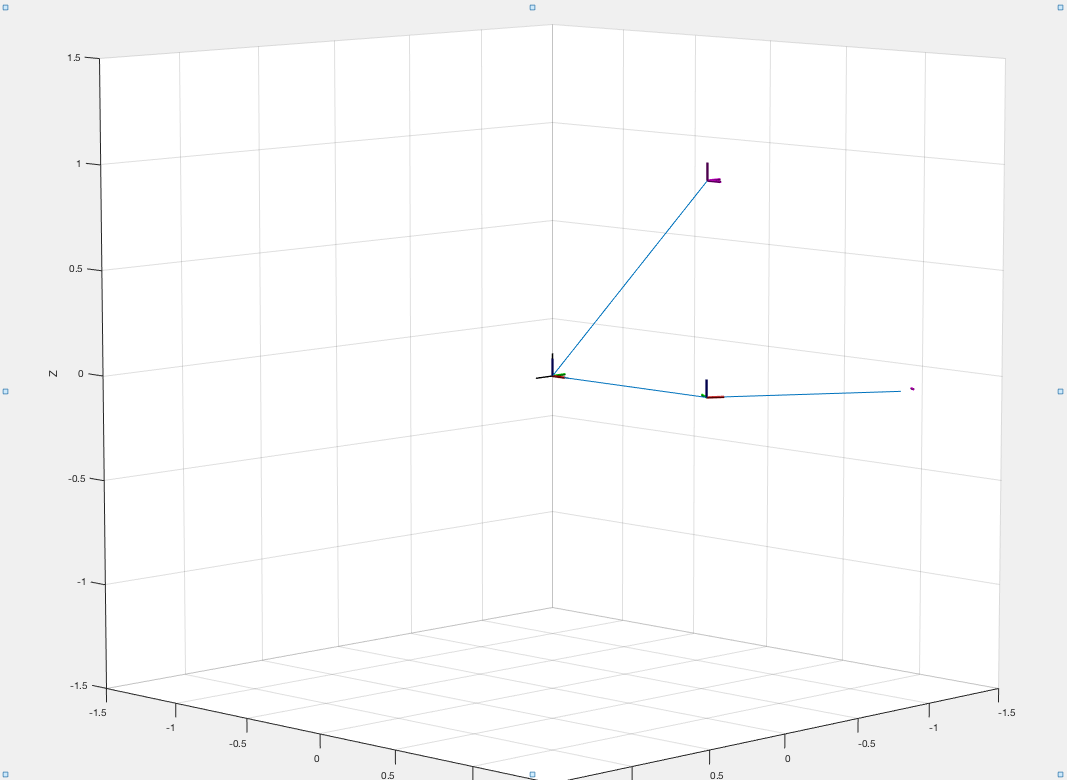

theta = linspace(0, pi/2, 50);
r = linspace(0.2, 1, 50);
        for i=1:50
            % Increment joint 1 
            q(1).JointPosition = theta(i);
            q(2).JointPosition = r(i);
            robot.show(q, 'PreservePlot', false);
            hold on
            drawnow
        end